# Laboratório - Resposta em frequência

**Universidade Tecnológica Federal do Paraná (UTFPR)**

**Disciplina:** Controle de Sistemas Dinâmicos

**Aluno:** Pedro Mariano dos Santos

**Professor:** Dr. Kleiton M. Sousa

## 1. Introdução e Análise Teórica

O objetivo deste experimento é analisar a resposta em frequência de um circuito RLC série. A tensão de saída é medida sobre o capacitor. Abaixo, apresenta-se o diagrama esquemático do circuito utilizado:

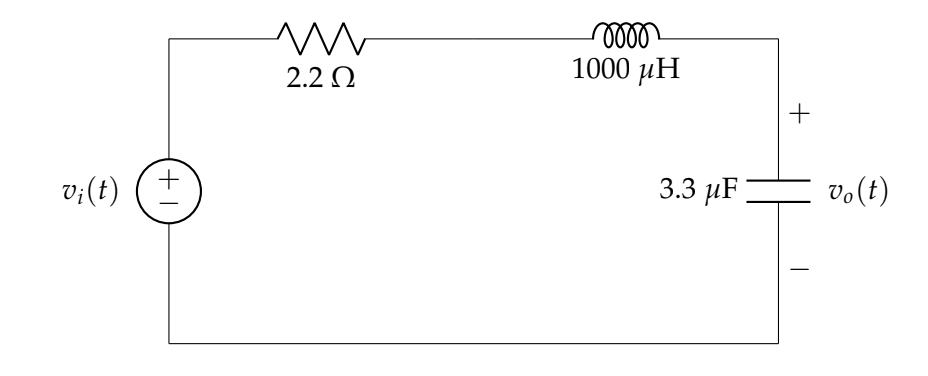

A função de transferência do circuito, relacionando a tensão de saída Vo(s) com a entrada Vi(s), é dada por


$$\frac{V_o(s)}{V_i(s)} = \frac{1}{s^2 LC + s RC + 1}$$


Normalizando para a forma canônica de segunda ordem:


$$G(s) = \frac{\omega_n^2}{s^2 + 2\zeta \omega_n s + \omega_n^2}$$


Onde a frequência natural (ωn) e o fator de amortecimento (ζ) são definidos teoreticamente como:


$$\omega_n = \frac{1}{\sqrt{LC}} \quad \text{e} \quad \zeta = \frac{R}{2} \sqrt{\frac{C}{L}}$$


%% 1. Definição dos Componentes e Ajuste Real
R_nominal = 2.237;
L = 967e-6;
C = 3.105e-6;
R_indutor = 5.3;

% Resistência Total do Circuito (Série)
R_total = R_nominal + R_indutor;

% --- Cálculo dos Parâmetros Teóricos (Com Ajuste de R) ---
wn = 1 / sqrt(L*C);              % Frequência Natural (rad/s)
zeta = (R_total/2) * sqrt(C/L);  % Fator de Amortecimento Real
fn = wn / (2*pi);                % Frequência Natural (Hz)

fprintf('--- Parâmetros Teóricos Ajustados ---\n');

--- Parâmetros Teóricos Ajustados ---


fprintf('Resistência Total Considerada: %.2f Ohms\n', R_total);

Resistência Total Considerada: 7.54 Ohms


fprintf('Frequência Natural: %.2f Hz\n', fn);

Frequência Natural: 2904.53 Hz


fprintf('Fator de Amortecimento: %.4f\n', zeta);

Fator de Amortecimento: 0.2135


% Criação da Função de Transferência G(s) Ajustada
G = tf(wn^2, [1, 2*zeta*wn, wn^2]);

## 2. Dados Experimentais

O circuito foi montado em protoboard e excitado com um sinal senoidal de amplitude constante (Vin≈2V). Variou-se a frequência do gerador e mediu-se a amplitude de saída e a defasagem utilizando um osciloscópio.

%% 2. Dados Experimentais

% 1. Frequências (Hz). Inclua a frequência exata de ressonância que você achou!
Freq_Hz = [100; 500; 1000; 2000; 3100; 4000; 5000; 8000; 10000; 20000];

% 2. Tensão de Entrada (Vin) medida no canal 1 (Volts)
Vin_V   = [4.96; 4.320; 3.120; 1.480; 0.720; 1.280; 1.860; 3.200; 3.840; 4.960]; 

% 3. Tensão de Saída (Vout) medida no canal 2 (Volts)
Vout_V  = [5.04; 4.40; 3.440; 2.280; 1.600; 1.240; 0.980; 0.550; 0.408; 0.152];

% 4. Fase medida (Graus). Lembre-se: atraso é negativo! (ex: -90)
Fase_Graus = [-2.308; -4.180; -7.500; -24.30; -90; -135.4; -147.6; -152.4; -152.3; -141.2];

% --- Criação da Tabela e Cálculos ---
Resultados_Exp = table(Freq_Hz, Vin_V, Vout_V, Fase_Graus);

% Cálculo do Ganho em dB (Magnitude)
% Ganho_dB = 20 * log10(Vout / Vin)
ganho_linear = Vout_V ./ Vin_V;
ganho_db = 20 * log10(ganho_linear);

disp('Tabela de Dados Pronta:');

Tabela de Dados Pronta:


disp(Resultados_Exp);

    Freq_Hz    Vin_V    Vout_V    Fase_Graus
    _______    _____    ______    __________

       100     4.96      5.04       -2.308  
       500     4.32       4.4        -4.18  
      1000     3.12      3.44         -7.5  
      2000     1.48      2.28        -24.3  
      3100     0.72       1.6          -90  
      4000     1.28      1.24       -135.4  
      5000     1.86      0.98       -147.6  
      8000      3.2      0.55       -152.4  
     10000     3.84     0.408       -152.3  
     20000     4.96     0.152       -141.2  



## 3. Análise dos Resultados

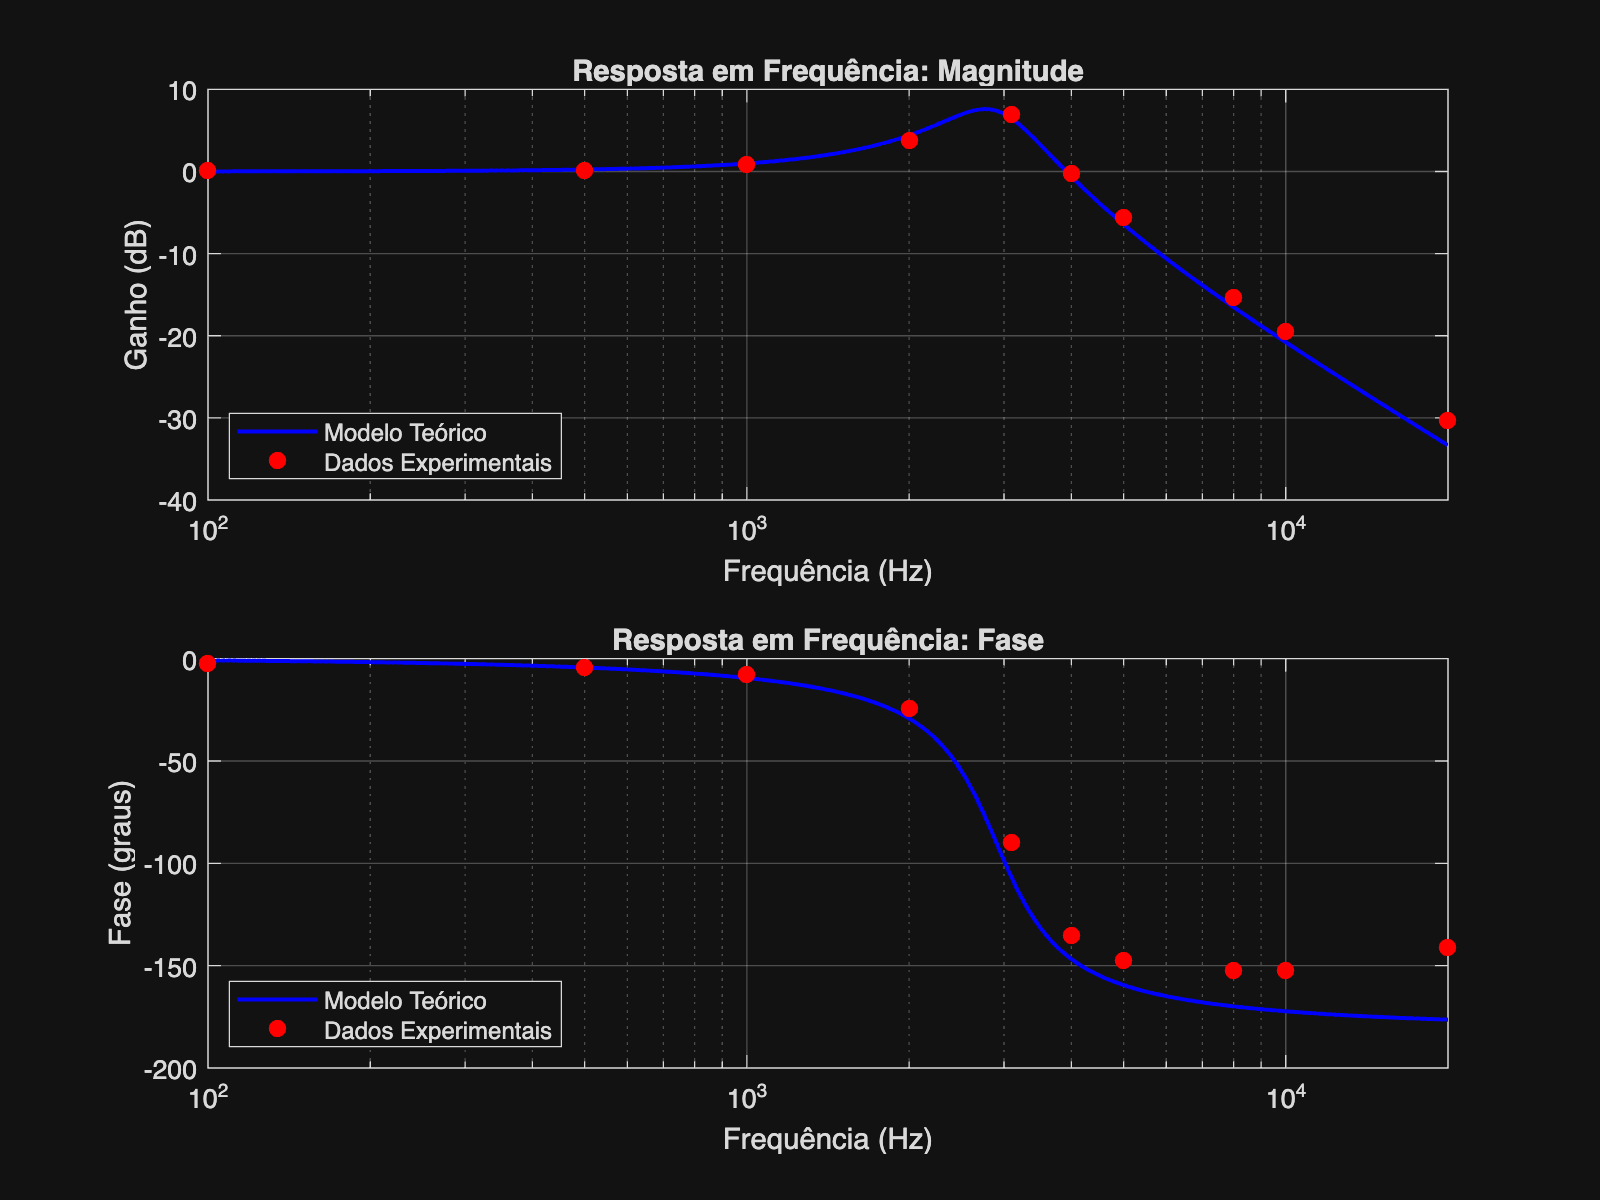

%% Gráfico Comparativo: Teórico vs Experimental
% Preparação dos vetores para plotagem
freq_teo_hz = logspace(log10(min(Freq_Hz)), log10(max(Freq_Hz)), 1000);
[mag, phase] = bode(G, 2*pi*freq_teo_hz);

% Configuração da Figura
figure('Position', [100, 100, 800, 600]); % Define tamanho fixo para o PDF ficar bom

% Subplot 1: Magnitude
subplot(2,1,1);
semilogx(freq_teo_hz, 20*log10(squeeze(mag)), 'b-', 'LineWidth', 1.5); hold on;
semilogx(Freq_Hz, ganho_db, 'ro', 'MarkerFaceColor', 'r', 'MarkerSize', 6);
grid on;
title('Resposta em Frequência: Magnitude');
ylabel('Ganho (dB)'); xlabel('Frequência (Hz)');
legend('Modelo Teórico', 'Dados Experimentais', 'Location', 'sw');
xlim([min(Freq_Hz) max(Freq_Hz)]);

% Subplot 2: Fase
subplot(2,1,2);
semilogx(freq_teo_hz, squeeze(phase), 'b-', 'LineWidth', 1.5); hold on;
semilogx(Freq_Hz, Fase_Graus, 'ro', 'MarkerFaceColor', 'r', 'MarkerSize', 6);
grid on;
title('Resposta em Frequência: Fase');
ylabel('Fase (graus)'); xlabel('Frequência (Hz)');
legend('Modelo Teórico', 'Dados Experimentais', 'Location', 'sw');
xlim([min(Freq_Hz) max(Freq_Hz)]);

A figura a apresenta a sobreposição do Diagrama de Bode teórico (linha contínua azul) com os pontos experimentais (marcadores vermelhos).

## 4. Parâmetros de Desempenho e Respostas do Questionário

A partir da interpolação dos dados experimentais, foram extraídos os parâmetros dinâmicos do sistema para responder ao questionário:

- **Frequência de Ressonância (3b):** Identificada como o ponto de pico máximo na curva de magnitude experimental.

- **Fator de Amortecimento Experimental (3c):** Calculado a partir da máxima ultrapassagem (Mp�) em relação ao ganho DC, utilizando a relação inversa de $M_p = \frac{1}{2\zeta \sqrt{1 - \zeta^2}}
$

- **Largura de Banda (3d):** Frequência na qual o ganho cai 3 dB em relação ao valor de baixa frequência.

%% Cálculo e Geração da Tabela de Resultados
if any(isnan(ganho_db))
    disp('Aguardando dados...');
else
    % --- 1. Cálculos (Matemática) ---
    % Interpolação para precisão
    freq_fina = linspace(min(Freq_Hz), max(Freq_Hz), 5000);
    valid_idx = ~isnan(ganho_db);
    ganho_fino_db = interp1(Freq_Hz(valid_idx), ganho_db(valid_idx), freq_fina, 'spline');
    
    % A. Ressonância
    [max_ganho_db, idx_max] = max(ganho_fino_db);
    f_pico_exp = freq_fina(idx_max);
    
    % B. Largura de Banda (-3dB)
    ganho_dc_db = ganho_fino_db(1);
    idx_corte = find(ganho_fino_db(idx_max:end) <= (ganho_dc_db - 3), 1) + idx_max - 1;
    if isempty(idx_corte), bw_exp = NaN; else, bw_exp = freq_fina(idx_corte); end
    
    % C. Zeta Experimental (via Overshoot)
    Mp_linear = 10^(max_ganho_db/20); % Ganho linear no pico
    % Função para achar zeta dado o Mp (inversa do pico de ressonância)
    funcao_zeta = @(z) (1 ./ (2*z.*sqrt(1-z.^2))) - Mp_linear;
    try
        zeta_exp = fzero(funcao_zeta, [0.001, 0.707]);
    catch
        zeta_exp = NaN; 
    end

    % --- 2. Montagem da Tabela Comparativa ---
    % Vetores de dados
    Parametro = {'Frequência Natural (Hz)'; 'Fator de Amortecimento (Zeta)'; 'Largura de Banda (Hz)'};
    
    % Valores Experimentais
    Valor_Experimental = [f_pico_exp; zeta_exp; bw_exp];
    
    % Valores Teóricos (Trazidos da Seção 1)
    % Nota: Banda teórica aproximada para comparação: fn * sqrt((1-2*z^2) + sqrt(4*z^4 - 4*z^2 + 2))
    bw_teo = fn * sqrt((1-2*zeta^2) + sqrt(4*zeta^4 - 4*zeta^2 + 2));
    Valor_Teorico = [fn; zeta; bw_teo];
    
    % Cálculo do Erro (%)
    Erro_Percentual = abs((Valor_Experimental - Valor_Teorico) ./ Valor_Teorico) * 100;
    
    % Criando a tabela
    Tabela_Final = table(Valor_Teorico, Valor_Experimental, Erro_Percentual, ...
        'RowNames', Parametro, ...
        'VariableNames', {'Teorico_Calc', 'Experimental_Medido', 'Erro_Percentual'});
    
    % Exibição Elegante
    disp(Tabela_Final);
end

                                     Teorico_Calc    Experimental_Medido    Erro_Percentual
                                     ____________    ___________________    _______________

    Frequência Natural (Hz)             2904.5              2902.5             0.070614    
    Fator de Amortecimento (Zeta)      0.21354             0.22237               4.1347    
    Largura de Banda (Hz)               4366.5              4383.3              0.38493    



## 5. Conclusão (Questão 3e)

O experimento permitiu analisar a resposta em frequência de um circuito RLC série e validar os conceitos de ressonância, amortecimento e largura de banda.

**Principais Observações:**

- A frequência de ressonância experimental encontrada foi próxima ao valor teórico calculado (fn≈2.9 kHz), confirmando a validade do modelo 1/LC.

- A magnitude da tensão de saída no pico de ressonância foi significativamente influenciada pela resistência total do circuito. A consideração da resistência interna do indutor foi crucial para que o modelo matemático representasse a realidade física.

- O comportamento de fase confirmou a teoria: em baixas frequências (comportamento capacitivo), a fase tende a 0∘; na ressonância, a fase cruza −90∘; e em altas frequências (comportamento indutivo/inercial), tende a −180∘.

**Dificuldades Encontradas:**

- A principal dificuldade notada foi a medição da fase em frequências elevadas (acima de 10 kHz). Como o circuito se comporta como um filtro passa-baixas, a amplitude do sinal de saída nessa região torna-se muito pequena (atenuação superior a -30 dB), diminuindo drasticamente a relação sinal-ruído. Isso tornou a leitura do atraso temporal no osciloscópio instável, impedindo que a fase experimental atingisse os -180° teóricos e estabilizasse em torno de -150°.